clc;
close all;
clear all;

tam = 5000;
[rpm,z] = datos_rpm();
tiempo = linspace(0,tam,z);

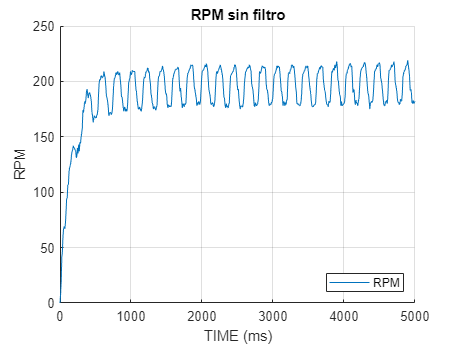

%Grafico de RPMs sin filtro 
hold on

plot(tiempo,rpm)
title('RPM sin filtro')
legend('RPM','Location','southeast')
ylabel('RPM')
xlabel('TIME (ms)')
grid on

%Aplicamos filtro media movil a las RPMs
rpm_media = movmedian(rpm,2);
%rpm_media2 = movmedian(rpm_media,2)
%rpm_mediaN = rpm_media/max(rpm_media)

% Calculamos el valor final/promedio
% Promedio de los ultimos ochenta valores
prom = 0;
for i = z-100:z
    prom = prom + rpm_media(i);
end
% Valor final 
Vf = prom/230

Vf = 86.6304

Vf283 = Vf*0.283

Vf283 = 24.5164

Vf632 = Vf*0.632

Vf632 = 54.7504

%Creamos lineas indicadoras para los porcentajes de interes
l75 = linspace(max(rpm_media)*0.75,max(rpm_media)*0.75,tam);
l63 = linspace(max(rpm_media)*0.632,max(rpm_media)*0.632,tam);
l45 = linspace(max(rpm_media)*0.45,max(rpm_media)*0.45,tam);
l28 = linspace(max(rpm_media)*0.283,max(rpm_media)*0.283,tam);
l15 = linspace(max(rpm_media)*0.15,max(rpm_media)*0.15,tam);
l0 = linspace(max(rpm_media)*0.0,max(rpm_media)*0.0,tam);
l100 = linspace(Vf*1.,Vf*1.,tam);

% % Calculamos las distancias para ver los puntos menores
% distancia = sqrt((rpm_media-l75).*(rpm_media-l75));
% [ndist,ind] = sort(distancia);
% figure
% hold on
% plot(l75)
% hold on
% c=0;
% if(c==0)
%     plot(tiempo(ind(1)),rpm_media(ind(1)),'*b')
%     c = c + 1;
% end

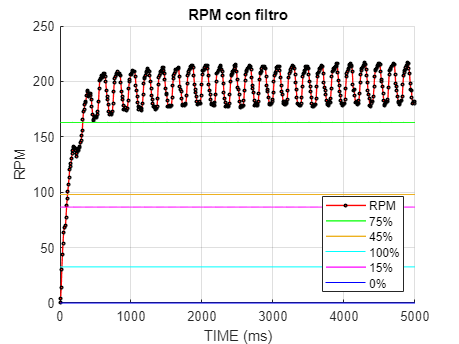

%Grafico de RPMs aplicando filtro de media movil y señalando los puntos de
%interes
figure 
hold on

plot(tiempo,rpm_media,'r','Marker',"o",'MarkerSize',2,'MarkerEdgeColor','k','LineWidth',1)
plot(l75,'g','LineWidth',1)
% plot(l63,'g')
plot(l45,'LineWidth',1)
% plot(l28,'b')
plot(l15,'c')
plot(l100,'m','LineWidth',1)
plot(l0,'b')

title('RPM sin filtro')
legend('RPM','75%','45%','100%','15%','0%','Location','southeast')
ylabel('RPM')
xlabel('TIME (ms)')
title('RPM con filtro')
% xlim([0 5])
grid on


% c = 1;
% c2 = 1;
% for i = 1:length(rpm_media)
%     if (i >= l63(c) - 1) || (i <= l63(c) + 1) 
%         plot(i,'Marker',"o","Color",'k')
%         c2 = c2+1
%     end
%     c = c+1;
% end


% Primer orden
% De la grafica
% t1 = 0.15*max(tiempo);
% t2 = 0.45*max(rpm_media)
% t3 = 0.75*max(rpm_media)
t1 = 88*10^-3

t1 = 0.0880

t2 = 262*10^-3

t2 = 0.2620

t3 = 1048*10^-3

t3 = 1.0480

Ts = 8*10^-3

Ts = 0.0080


%Cálculo de valores      
% Valor final 
Vf = prom/230

Vf = 86.6304

Vf283 = Vf*0.283

Vf283 = 24.5164

Vf632 = Vf*0.632

Vf632 = 54.7504


deltaY = Vf

deltaY = 86.6304

deltaU = 1

deltaU = 1


theta = 0.002

theta = 0.0020

Tao = t2-theta

Tao = 0.2600

tmin = 4*Tao

tmin = 1.0400

tmax = 5*Tao

tmax = 1.3000

k = deltaY

k = 86.6304


syms s e
% e = 2.7182818284;

G1 = (deltaY*(e^(-theta*s)))/(Tao*s+deltaU)

$$G1 = \frac{3985}{46\,e^{s/500}\,\left(\frac{13\,s}{50}+1\right)}$$

num = 196.8813;
den = [0.26 1];
Gfinal = tf(num,den)

Gfinal =
 
    196.9
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



% Segundo orden
x = (t2 - t1)/(t3 - t1)

x = 0.1813

chi = (0.0805 - 5.547*(0.475 - x)^2)/(x - 0.356)

chi = 2.2784

F2chi = (2.6 * chi) - 0.6

F2chi = 5.3238

Wn = F2chi/(t3 - t1)

Wn = 5.5456

F3chi = 0.922 * (1.66)^chi

F3chi = 2.9256

thetap = t2 - F3chi/Wn

thetap = -0.2656


tao1 = (chi + sqrt(chi^2-1))/Wn

tao1 = 0.7800

tao2 = (chi - sqrt(chi^2-1))/Wn

tao2 = 0.0417


Gp = (k*e^-thetap*s)/(tao1*s + 1)*(tao2*s+1)

$$Gp = \frac{3985\,e^{597986151884035/2251799813685248}\,s\,\left(\frac{6007859537737063\,s}{144115188075855872}+1\right)}{46\,\left(\frac{7025614142158741\,s}{9007199254740992}+1\right)}$$